# Exercice 11 - Optimisation multi-objectifs 

## Données

Un dispatcher d'énergies dispose de 5  centrales thermiques de différentes technologiques qui produisent de l'électricité. Il est capable de prédire le coût de chaque centrale à partir d'une relation de type : 


$$C_I \left(P_I \right)=a_I {\left(P_I \right)}^2 +b_I {\left(P_I \right)} +c_I$$


$C_I$ est le coût de production selon la puissance produite ($P_I$) pour l'unité *I*. 

Chaque centrale a des limites de production : $P_{I,\min } {\le P}_I \le P_{I,\max }$

Chaque centrale produit des émissions polluantes. Le dispatcher dispose de relation pour estimer la quantité totale ($T_I$) de polluants produite en kg/j par chaque centrale en fonction de sa puissance thermique ($P_I$) :  


$$T_I \left(P_I \right)=d_I {\left(P_I \right)}^2 +e_I {\left(P_I \right)} +f_I$$


Les données des 5 centrales sont disponibles dans le fichier `data_Exercice11.mat` (`load data_Exercice11`): coefficients `A, B, C, D, E` et `F` des deux formules ci-dessus ainsi que `Pmin` et `Pmax`. 

Toutes les puissances sont exprimées en MW.

clear 

load data_Exercice11;

## Partie 1

% On cherche dans cette partie à minimiser les coûts tout en répondant à la
%demande.
% Les variables d'optimisation sont les 5 puissances demandées à chacune
% des centrales. 


#### 1.1 : Définition des variables du problème

N=5;
Demande = 400;


#### 1.2 : Définition de la fonction objectif à minimiser

% Il s'agit de minimiser le coût total de production
f_obj = @(x) (x.^2*A + x*B + sum(C));

#### 1.3 : Définition des contraintes linéaires

Aineq = -ones(1,N);

Bineq = -Demande;

%Il n'y a aucune contrainte égalité dans cette partie.
Aeq = [];
Beq = [];


#### 1.4 : Définition des bornes du problème

lb = Pmin;
ub = Pmax;


#### 1.5 : Solver fmincon pour résolution du problème

% x0 est choisi pour chaque variable à environ la moyenne de Pmin et Pmax
x0 = [100 150 120 150 35];
options = optimoptions('fmincon','Display','iter','Diagnostics','on');
[x1,fval1,flag,out]=fmincon(f_obj,x0,Aineq,Bineq,Aeq,Beq,lb,ub,'',options);

____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.848530e+05    0.000e+00    1.233e+03
    1      12    1.488317e+05    0.000e+00    8.762e+02    7.500e+01
    2      18    1.481819e+05    0.00

#### 1.6 : Définition des contraintes non-linéaires 

%Il n'y a aucune contrainte non-linéaire dans cette partie.


#### 1.7 : Affichage des résultats pour une demande fixée 

disp('Solution trouvée :')

Solution trouvée :


disp(x1)

  102.8442   90.0000   76.7303   77.4255   53.0000



disp('Valeur de la fonction à la solution trouvée : ')

Valeur de la fonction à la solution trouvée : 


disp(fval1)

   1.3146e+05



disp('Valeur flag de fmincon :')

Valeur flag de fmincon :


disp(flag)

     1



#### 1.7 : Répétition du code pour tracer le graphe

Le code fonctionne désormais pour une seule valeur de demande : pour tracer le graphe, il s'agit de stocker les valeurs

des puissances optimisées par centrale pour chaque valeur de la demande.

% ListeDemande est choisie de telle sorte à avoir 10 valeurs sur l'ensemble
% de la plage de possibilités de puissances : de 281 à 998. Les valeurs
% extrêmes ne sont pas très intéressantes : toutes les puissances seraient
% alors au min ou toutes au max. 

ListeDemande = 300:75:975;
x0 = [100 150 120 150 35];
Result_Puissances = [];
Result_Couts = [];
% Ici, j'ai stocké les résultats des puissances dans la matrice
% Result_Puissances et les couts dans Result_Couts

for i=ListeDemande
    
    Bineq = -i;
    f_obj = @(x) (x.^2*A + x*B + sum(C));

    options = optimoptions('fmincon','Display','iter','Diagnostics','on');
    [x1p,fval1p,flag,out]=fmincon(f_obj,x0,Aineq,Bineq,Aeq,Beq,lb,ub,'',options);
    Result_Puissances = [Result_Puissances x1p'];
    Result_Couts= [Result_Couts fval1p]
end

____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.848530e+05    0.000e+00    1.233e+03
    1      12    1.106538e+05    0.000e+00    7.486e+02    1.020e+02
    2      18    1.080698e+05    0.00

Result_Couts = 8.8094e+04

____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.848530e+05    0.000e+00    1.233e+03
    1      12    1.310740e+05    0.000e+00    8.193e+02    8.707e+01
    2      18    1.304467e+05    0.00

Result_Couts = 	1.0e+05 *

    0.8809    1.1651


____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.848530e+05    0.000e+00    1.232e+03
    1      12    1.877192e+05    0.000e+00    9.891e+02    5.090e+01
    2      18    1.867780e+05    0.00

Result_Couts = 	1.0e+05 *

    0.8809    1.1651    1.6631


____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.848530e+05    0.000e+00    1.228e+03
    1      12    2.519384e+05    0.000e+00    1.104e+03    1.662e+01
    2      18    2.406673e+05    0.00

Result_Couts = 	1.0e+05 *

    0.8809    1.1651    1.6631    2.2816


____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.848530e+05    4.500e+01    5.704e+02
    1      12    2.679221e+05    4.350e+01    4.306e+02    2.567e+01
    2      18    2.678373e+05    4.25

Result_Couts = 	1.0e+05 *

    0.8809    1.1651    1.6631    2.2816    3.0045


____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.848530e+05    1.200e+02    5.704e+02
    1      12    2.704283e+05    1.161e+02    4.310e+02    2.504e+01
    2      18    2.714687e+05    1.14

Result_Couts = 	1.0e+05 *

    0.8809    1.1651    1.6631    2.2816    3.0045    3.8317


____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.848530e+05    1.950e+02    5.704e+02
    1      12    2.728232e+05    1.888e+02    4.314e+02    2.450e+01
    2      18    2.746845e+05    1.86

Result_Couts = 	1.0e+05 *

    0.8809    1.1651    1.6631    2.2816    3.0045    3.8317    4.7671


____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.848530e+05    2.700e+02    5.704e+02
    1      12    2.751140e+05    2.616e+02    4.314e+02    2.402e+01
    2      18    2.776524e+05    2.58

Result_Couts = 	1.0e+05 *

    0.8809    1.1651    1.6631    2.2816    3.0045    3.8317    4.7671    5.8452


____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.848530e+05    3.450e+02    5.704e+02
    1      12    2.773074e+05    3.346e+02    4.314e+02    2.361e+01
    2      18    2.804566e+05    3.30

Result_Couts = 	1.0e+05 *

    0.8809    1.1651    1.6631    2.2816    3.0045    3.8317    4.7671    5.8452    7.1088


____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.848530e+05    4.200e+02    5.704e+02
    1      12    2.794093e+05    4.076e+02    4.314e+02    2.325e+01
    2      18    2.831480e+05    4.03

Result_Couts = 	1.0e+05 *

    0.8809    1.1651    1.6631    2.2816    3.0045    3.8317    4.7671    5.8452    7.1088    8.5986


#### 1.7 : Affichage des résultats

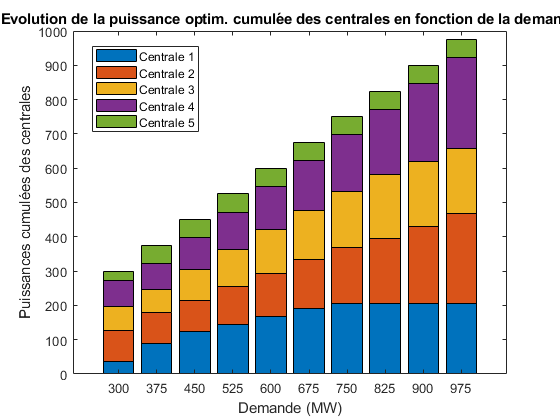


figure
bar(ListeDemande,Result_Puissances,'stacked')
xlabel('Demande (MW)')
ylabel('Puissances cumulées des centrales')
title(sprintf(['Evolution de la puissance optim. cumulée des centrales en fonction de la demande']))
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")

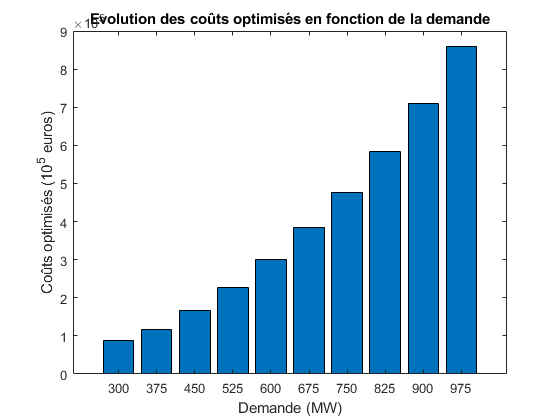

figure
bar(ListeDemande,Result_Couts,'stacked')
xlabel('Demande (MW)')
ylabel('Coûts optimisés (10^5 euros)')
title(sprintf(['Evolution des coûts optimisés en fonction de la demande']))

## Partie 2

% On cherche dans cette partie à minimiser les émissions polluantes tout en répondant à la
%demande.
% Les variables d'optimisation sont les 5 puissances demandées à chacune
% des centrales. 


#### 2.1 : Définition des variables du problème

Demande = 400; % La demande est imposée dans cette partie


#### 2.2 : Définition de la fonction objectif à minimiser

% Il s'agit de minimiser les émissions polluantes, on introduit alors les
% matrices D, E et F
f_obj2 = @(x) (x.^2*D + x*E + 24*sum(F));

#### 2.3 : Définition des contraintes linéaires

% Les contraintes sont les mêmes que précédemment.
Bineq=-Demande;
% Il n'y a aucune contrainte égalité dans cette partie.

#### 2.4 : Définition des bornes du problème

% Ce sont les mêmes que précédemment.

#### 2.5 : Solver fmincon pour résolution du problème

% x0 est choisi pour chaque variable à environ la moyenne de Pmin et Pmax
x0 = [100 150 120 150 35];

options = optimoptions('fmincon','Display','iter','Diagnostics','on');
[x2,fval2,flag,out]=fmincon(f_obj2,x0,Aineq,Bineq,Aeq,Beq,lb,ub,'',options);

____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*D+x*E+24*sum(F))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.055967e+05    0.000e+00    1.200e+03
    1      12    9.726688e+04    0.000e+00    7.634e+02    7.552e+01
    2      18    9.209617e+04    0

#### 2.6 : Définition des contraintes non-linéaires 

%Il n'y a aucune contrainte non-linéaire dans cette partie.

#### 2.7 : Affichage des résultats et  analyse

disp('Solution trouvée :')

Solution trouvée :


disp(x2)

   71.6220   90.0000   68.0000  129.7628   40.6152



disp('Valeur de la fonction à la solution trouvée : ')

Valeur de la fonction à la solution trouvée : 


disp(fval2)

   8.7700e+04



disp('Valeurflag de fmincon :')

Valeurflag de fmincon :


disp(flag)

     1



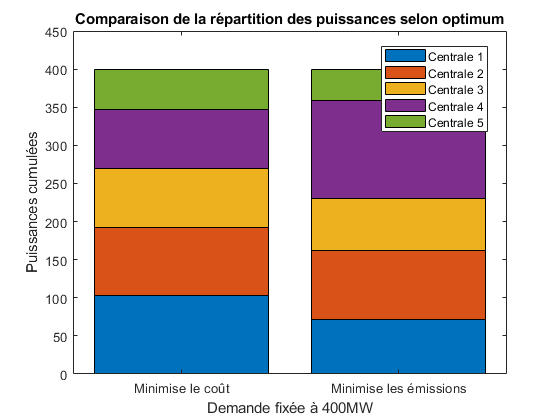


% En cherchant à minimiser les coûts de production pour une demande de
% 400MW, on obtient que le coût serait de 1.3146e+05 euros et les puissances
% sont alors :  102.8442   90.0000   76.7303   77.4255   53.0000

% En cherchant à minimiser les émissions polluantes pour cette même
% demande, on obtient 8.7089e+04 kg/j et les puissances sont alors :
%    71.6220   90.0000   68.0000  129.7628   40.6152
% Sans surprise, la fonction objectif économique donne un moins bon
% résultat avec l'optimum environnemental et la fonction objectif
% environnemental donne un moins bon résultat avec l'optimum économique 

% f_obj(x2)
% ans = 1.4868e+05 : supérieur à 1.3146e+05
% 
% f_obj2(x)
% ans = 9.6451e+04 : supérieur à 8.7089e+04

%Un graphique vaut mille mots :
Comp=[x1 ; x2];
Dem=categorical({'Minimise le coût','Minimise les émissions'});
figure
bar(Dem,Comp,'stacked');
xlabel('Demande fixée à 400MW')
ylabel('Puissances cumulées')
title(sprintf(['Comparaison de la répartition des puissances selon optimum']))
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")

## Partie 3

#### 3.1 : Méthode de pondération

lb = Pmin;
ub = Pmax;

Aineq = -ones(1,N);
Bineq = -Demande;

Aeq = [];
Beq = [];

N=5;
Demande = 400;

x0 = [100 150 120 150 35];
val_pareto_pond=[];
f1val=[];
f2val=[];

for i=0:10
    w1=i/10;
    w2=1-w1;
    FUN = @(x) w1*(x.^2*A + x*B + sum(C)) + w2*(x.^2*D + x*E + sum(F));
    options = optimoptions('fmincon','Display','iter','Diagnostics','on');
    [X,FVAL,flag,out]=fmincon(FUN,x0,Aineq,Bineq,Aeq,Beq,lb,ub,'',options);
    val_pareto_pond = [val_pareto_pond FVAL];
    f1val=[f1val f_obj(X)];
    f2val=[f2val f_obj2(X)];
end

____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)w1*(x.^2*A+x*B+sum(C))+w2*(x.^2*D+x*E+sum(F))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.049860e+05    0.000e+00    1.200e+03
    1      12    9.665623e+04    0.000e+00    7.634e+02    7.552e+01
    2      

x_pond =    71.6220   90.0000   68.0000  129.7628   40.6152


____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)w1*(x.^2*A+x*B+sum(C))+w2*(x.^2*D+x*E+sum(F))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.129727e+05    0.000e+00    1.178e+03
    1      12    1.004373e+05    0.000e+00    7.604e+02    7.760e+01
    2      

x_pond =    71.6220   90.0000   68.0000  129.7628   40.6152   78.1635   90.0000   68.0000  117.8750   45.9616


____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)w1*(x.^2*A+x*B+sum(C))+w2*(x.^2*D+x*E+sum(F))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.209594e+05    0.000e+00    1.160e+03
    1      12    1.048864e+05    0.000e+00    7.631e+02    7.872e+01
    2      

x_pond =    71.6220   90.0000   68.0000  129.7628   40.6152   78.1635   90.0000   68.0000  117.8750   45.9616   82.9448   90.0000   68.0000  108.5540   50.5013


____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)w1*(x.^2*A+x*B+sum(C))+w2*(x.^2*D+x*E+sum(F))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.289461e+05    0.000e+00    1.169e+03
    1      12    1.117325e+05    0.000e+00    7.784e+02    7.755e+01
    2      

x_pond =    71.6220   90.0000   68.0000  129.7628   40.6152   78.1635   90.0000   68.0000  117.8750   45.9616   82.9448   90.0000   68.0000  108.5540   50.5013   87.1802   90.0000   68.0000  101.8198   53.0000


____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)w1*(x.^2*A+x*B+sum(C))+w2*(x.^2*D+x*E+sum(F))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.369328e+05    0.000e+00    1.178e+03
    1      12    1.181179e+05    0.000e+00    7.933e+02    7.663e+01
    2      

x_pond =    71.6220   90.0000   68.0000  129.7628   40.6152   78.1635   90.0000   68.0000  117.8750   45.9616   82.9448   90.0000   68.0000  108.5540   50.5013   87.1802   90.0000   68.0000  101.8198   53.0000   91.6085   90.0000   68.0000   97.3915   53.0000


____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)w1*(x.^2*A+x*B+sum(C))+w2*(x.^2*D+x*E+sum(F))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.449195e+05    0.000e+00    1.187e+03
    1      12    1.240856e+05    0.000e+00    8.079e+02    7.594e+01
    2      

x_pond =    71.6220   90.0000   68.0000  129.7628   40.6152   78.1635   90.0000   68.0000  117.8750   45.9616   82.9448   90.0000   68.0000  108.5540   50.5013   87.1802   90.0000   68.0000  101.8198   53.0000   91.6085   90.0000   68.0000   97.3915   53.0000   95.3538   90.0000   68.0000   93.6462   53.0000


____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)w1*(x.^2*A+x*B+sum(C))+w2*(x.^2*D+x*E+sum(F))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.529062e+05    0.000e+00    1.196e+03
    1      12    1.296729e+05    0.000e+00    8.221e+02    7.545e+01
    2      

x_pond =    71.6220   90.0000   68.0000  129.7628   40.6152   78.1635   90.0000   68.0000  117.8750   45.9616   82.9448   90.0000   68.0000  108.5540   50.5013   87.1802   90.0000   68.0000  101.8198   53.0000   91.6085   90.0000   68.0000   97.3915   53.0000   95.3538   90.0000   68.0000   93.6462   53.0000   98.5629   90.0000   68.0000   90.4371   53.0000


____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)w1*(x.^2*A+x*B+sum(C))+w2*(x.^2*D+x*E+sum(F))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.608929e+05    0.000e+00    1.205e+03
    1      12    1.349132e+05    0.000e+00    8.360e+02    7.513e+01
    2      

x_pond =    71.6220   90.0000   68.0000  129.7628   40.6152   78.1635   90.0000   68.0000  117.8750   45.9616   82.9448   90.0000   68.0000  108.5540   50.5013   87.1802   90.0000   68.0000  101.8198   53.0000   91.6085   90.0000   68.0000   97.3915   53.0000   95.3538   90.0000   68.0000   93.6462   53.0000   98.5629   90.0000   68.0000   90.4371   53.0000  101.3433   90.0000   68.0000   87.6567   53.0000


____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)w1*(x.^2*A+x*B+sum(C))+w2*(x.^2*D+x*E+sum(F))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.688796e+05    0.000e+00    1.214e+03
    1      12    1.398361e+05    0.000e+00    8.497e+02    7.496e+01
    2      

x_pond =    71.6220   90.0000   68.0000  129.7628   40.6152   78.1635   90.0000   68.0000  117.8750   45.9616   82.9448   90.0000   68.0000  108.5540   50.5013   87.1802   90.0000   68.0000  101.8198   53.0000   91.6085   90.0000   68.0000   97.3915   53.0000   95.3538   90.0000   68.0000   93.6462   53.0000   98.5629   90.0000   68.0000   90.4371   53.0000  101.3433   90.0000   68.0000   87.6567   53.0000  103.4324   90.0000   68.6246   84.9430   53.0000


____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)w1*(x.^2*A+x*B+sum(C))+w2*(x.^2*D+x*E+sum(F))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.768663e+05    0.000e+00    1.223e+03
    1      12    1.444678e+05    0.000e+00    8.631e+02    7.492e+01
    2      

x_pond =    71.6220   90.0000   68.0000  129.7628   40.6152   78.1635   90.0000   68.0000  117.8750   45.9616   82.9448   90.0000   68.0000  108.5540   50.5013   87.1802   90.0000   68.0000  101.8198   53.0000   91.6085   90.0000   68.0000   97.3915   53.0000   95.3538   90.0000   68.0000   93.6462   53.0000   98.5629   90.0000   68.0000   90.4371   53.0000  101.3433   90.0000   68.0000   87.6567   53.0000  103.4324   90.0000   68.6246   84.9430   53.0000  103.2882   90.0000   72.6956   81.0162   53.0000


____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)w1*(x.^2*A+x*B+sum(C))+w2*(x.^2*D+x*E+sum(F))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.848530e+05    0.000e+00    1.233e+03
    1      12    1.488317e+05    0.000e+00    8.762e+02    7.500e+01
    2      

x_pond =    71.6220   90.0000   68.0000  129.7628   40.6152   78.1635   90.0000   68.0000  117.8750   45.9616   82.9448   90.0000   68.0000  108.5540   50.5013   87.1802   90.0000   68.0000  101.8198   53.0000   91.6085   90.0000   68.0000   97.3915   53.0000   95.3538   90.0000   68.0000   93.6462   53.0000   98.5629   90.0000   68.0000   90.4371   53.0000  101.3433   90.0000   68.0000   87.6567   53.0000  103.4324   90.0000   68.6246   84.9430   53.0000  103.2882   90.0000   72.6956   81.0162   53.0000


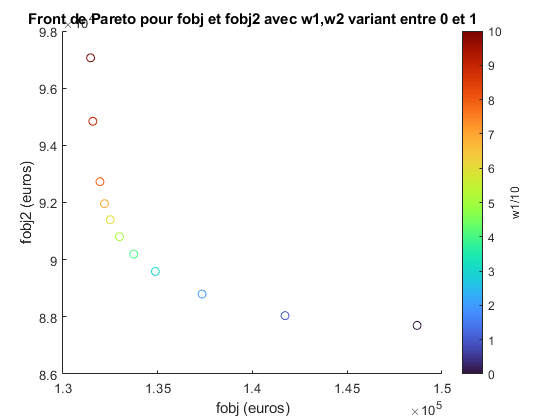


Z=0:10;
scatter(f1val,f2val,[],Z)
colormap turbo
c = colorbar;
c.Label.String = 'w1/10'; 
xlabel('fobj (euros)')
ylabel('fobj2 (euros)')
title('Front de Pareto pour fobj et fobj2 avec w1,w2 variant entre 0 et 1')

#### 3.2 : Méthode du but à atteindre

% x_but=[];
% feval_but=[];
% % On choisit de faire payer au maximum les industriels sur leurs rejets
% % supplémentaires : 0,5euro/kg/j
% taxe=0.5;
% f_obj_but = @(P) sum([A.*P.^2+B.*P+C]) + sum([D.*P.^2+E.*P+F])*taxe; 
% 
% for i=1:length(Z)
%     fun_but = @(x) [f_obj_but(x) ; f_obj2(x)]; 
%     goal = [FVAL FVAL]; 
%     Poids = [Z(i) 1-Z(i)]; 
%     [xbut, fvalbut, factorbut,flagbut,outputbut] = fgoalattain(fun_but,x0,goal,Poids,A,B,Aeq,Beq,lb,ub,'');
%     x_but=[x_but xbut];
%     feval_but=[feval_but [f_obj_but(xbut) f_obj2(xbut)]'];
% end

## Conclusions

A partir de l'ensemble des résultats obtenus, quelles sont vos conclusions générales sur l'optimum de fonctionnement ?  

Je n'ai pas réussi à coder la méthode du but à atteindre, un message d'erreur que je n'arrive pas à résoudre apparaît. Je ne pourrai donc pas la comparer à celle de la pondération.

Cependant, étant un fervent écologiste, je pondérerai à 80% la fonction environnement et à 20% la fonction cout. Ainsi, la valeur des deux fonctions objectifs seraient 131 573 euros pour la fonction économique et 94 841euros pour la fonction environnement d'après Pareto.

Les puissances correspondantes seraient  : 53.0000  103.4324   90.0000   68.6246   84.9430   53.0000